**Problem 1**

Red = x

Green = y

Blue = z

clear clc;
syms theta_1 theta_2 theta_3 theta_4 theta_5 real
a1 = 50e-3;
a2 = 93e-3;
a3 = 93e-3;
a4 = 50e-3;
a5 = 45e-3;
a6 = 35e-3;

theta = [theta_1, theta_2, theta_3, theta_4, theta_5];
d = [a1,0,0,0,0];
a = [0,a2,a3,a4,a6];
alpha = [90,0,0,0,0];

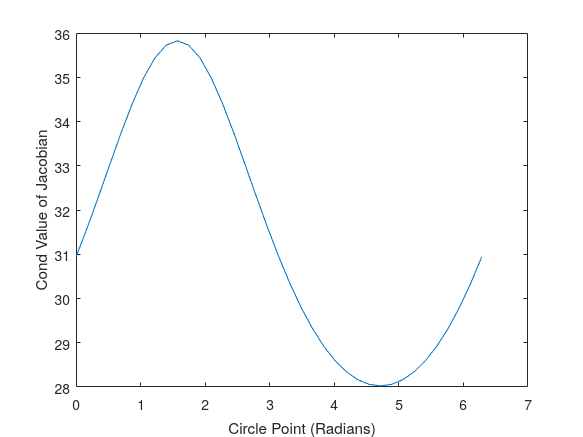

A1_0 = dhTransform(theta(1), d(1), a(1), alpha(1))
A2_1 = dhTransform(theta(2),d(2),a(2),alpha(2))
A3_2 = dhTransform(theta(3),d(3),a(3),alpha(3))
A4_3 = dhTransform(theta(4),d(4),a(4),alpha(4))
T4_0 = simplify(A1_0*A2_1*A3_2*A4_3)
A5_4 = [1,0,0,a6-a4;
        0,1,0,a5;
        0,0,1,0;
        0,0,0,1];
T5_0 = simplify(T4_0*A5_4)

**Problem 2**

Decouple after first 3 joints: Oc is O3, 

First joint controls moves the direction of the arm, and is therefore partially responsible for x and y

% We can find theta_1 without doing any decoupling, since theta_1 is the
% only rotational joint in the x-y plane of the base frame
o4 = T4_0(1:3,4);
theta_1 = atan2(o4(2),o4(1));

% Since the robot is 4DOF, and w is given, we can rewrite the x and y
% component of x4_0 as a function of w
x4_0 = T4_0(1:3,1)
w = x4_0(3);
x4_0 = [sqrt(1-w^2)*cos(theta_1);
    sqrt(1-w^2)*sin(theta_1);
    w]
% Kinematic decoupling
o3 = o4 - a(4)*x4_0;
oc = o3;

% Matlab says atan2(y,x). Which should i use? ----------------------

% Now we can find theta_2, 3 and 4
s = oc(3) - d(1);
r=sqrt(oc(1)^2+oc(2)^2);
c3 = (r^2 + s^2 - a(2)^2-a(3)^2)/(2*a(2)*a(3));

theta_3 = atan2(sqrt(1-c3^2), c3);
theta_2 = atan2(s,r) - atan2(a(3)*sin(atan2(c3,sqrt(1-c3^2))),a(2)+a(3)*c3);

% Isolate theta_4 from w
theta_4 = asin(w) - (theta_2 + theta_3);


Use problem 3 to check problem 2. They should line up

R=32e-3;
pc_0=[150e-3;0;120e-3];

o4 = pc_0+R*[0;cos(0);sin(0)]

[q1,q2,q3,q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3)
T4_0_f = matlabFunction(T4_0);

T4_0_f(q1,q2,q3,q4)

**Problem 3**

angles = linspace(0,2*pi,37);

x_circle = pc_0(1) * ones(size(angles));
y_circle = R * cos(angles) + pc_0(2); 
z_circle = R * sin(angles) + pc_0(3);

o4_matrix = [x_circle; y_circle; z_circle];
num_points = size(o4_matrix, 2); 

for i = 1:num_points
    o4 = o4_matrix(:, i); 
    [q1, q2, q3, q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3);
    
    q1_all(i) = q1;
    q2_all(i) = q2;
    q3_all(i) = q3;
    q4_all(i) = q4;

    FK = T4_0_f(q1_all(i),q2_all(i),q3_all(i),q4_all(i));
    
    FK_points(:,i) = FK(1:3,4);

    FK_r = FK(1:3,3);
  
end

figure(2)
plot3(FK_points(1,:),FK_points(2,:),FK_points(3,:),'ro')
hold on
plot3(x_circle, y_circle, z_circle, '-b', 'LineWidth', 2); 
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Circle Plot');


**Problem 4**


T1_0 = simplify(A1_0);
T2_0 = simplify(A1_0*A2_1);
T3_0 = simplify(A1_0*A2_1*A3_2);

o0_j = [0,0,0]';
o1_j = T1_0(1:3,4);
o2_j = T2_0(1:3,4);
o3_j = T3_0(1:3,4);
o4_j = T4_0(1:3,4);
o5_j = T5_0(1:3,4);

o_j_matrix4 = [o0_j, o1_j, o2_j, o3_j, o4_j];
o_j_matrix5 = [o0_j, o1_j, o2_j, o3_j, o4_j, o5_j];

z0_j = [0,0,1]';
z1_j = T1_0(1:3,3);
z2_j = T2_0(1:3,3);
z3_j = T3_0(1:3,3);
z4_j = T4_0(1:3,3);

z_j_matrix4 = [z0_j, z1_j, z2_j, z3_j];
z_j_matrix5 = [z0_j, z1_j, z2_j, z3_j, z4_j];


J4 = Jacobi_Revolute(o_j_matrix4, z_j_matrix4, 5);
J5 = Jacobi_Revolute(o_j_matrix5, z_j_matrix5, 6);

J4_f = matlabFunction(J4);
J5_f = matlabFunction(J5);

q1_0 = q1_all(1);
q2_0 = q2_all(1);
q3_0 = q3_all(1);
q4_0 = q4_all(1);

q1_90 = q1_all(10);
q2_90 = q2_all(10);
q3_90 = q3_all(10);
q4_90 = q4_all(10);

q1_180 = q1_all(19);
q2_180 = q2_all(19);
q3_180 = q3_all(19);
q4_180 = q4_all(19);

q1_270 = q1_all(28);
q2_270 = q2_all(28);
q3_270 = q3_all(28);
q4_270 = q4_all(28);


J4_0 = J4_f(q1_0,q2_0,q3_0,q4_0)
J4_90 = J4_f(q1_90,q2_90,q3_90,q4_90)
J4_180 = J4_f(q1_180,q2_180,q3_0,q4_180);
J4_270 = J4_f(q1_270,q2_270,q3_270,q4_270);

J5_0 = J5_f(q1_0,q2_0,q3_0,q4_0)
J5_90 = J5_f(q1_90,q2_90,q3_90,q4_90)
J5_180 = J5_f(q1_180,q2_180,q3_0,q4_180);
J5_270 = J5_f(q1_270,q2_270,q3_270,q4_270);

**Problem 5**

Where is the center of where the angular velocities are calculated? Center of circle or robot?

v = [0 ; -3e-3 ; 0 ; 0 ];

o_point_vel = pc_0+R*[0;cos(pi/2);sin(pi/2)];
[q1, q2, q3, q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3);
T_problem5 = T4_0_f(q1,q2,q3,q4)
Ryx = T_problem5(2,1);
Rxx = T_problem5(1,1);
Mask = [1,0,0,0,0,0;
        0,1,0,0,0,0;
        0,0,1,0,0,0;
        0,0,0,Ryx, -Rxx, 0]
A4x6 = J4_90;
A4x4 = Mask*J4_90
J_plus = ((transpose(A4x4)*A4x4)^-1)*transpose(A4x4)     % Underactuated arm (4 DOF < 6 DOF)
q_dot = J_plus*v

**Problem 8**

% Initialize array to store condition numbers
cond_values = zeros(1, num_points);

% Calculate condition numbers for each point
for i = 1:num_points
    cond_values(i) = cond(J4_f(q1_all(i), q2_all(i), q3_all(i), q4_all(i)));
end

plot(angles, cond_values)
xlabel("Circle Point (Radians)")
ylabel("Cond Value of Jacobian")